# Complex Fourier Series

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

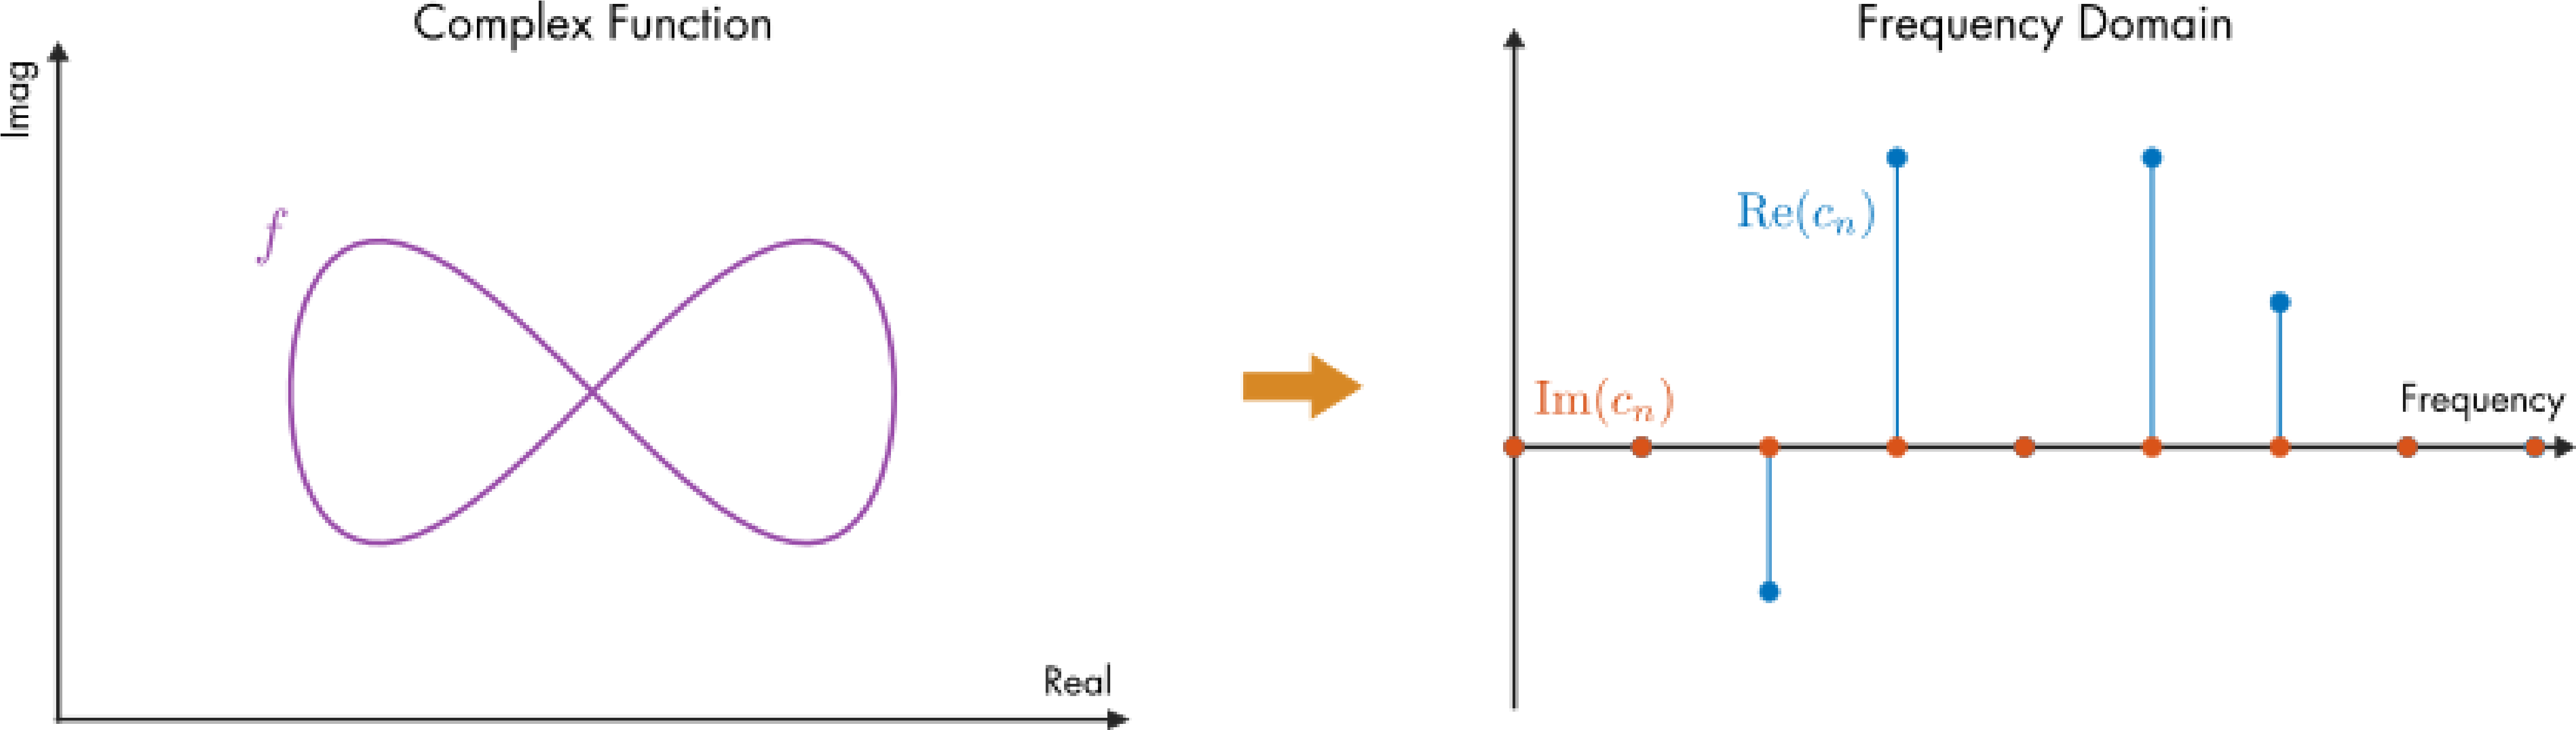

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and they will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction

Fourier series can be defined using sines and cosines:


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


or a single cosine parameterized in terms of magnitude $A_n$ and phase $\phi_n$:


$$f(t) = \frac{A_0}{2} +  \sum_{n=1}^{\infty} A_n \cos\left( \frac{ n \pi } {L}  t - \phi_n \right)$$


These forms are intuitively simple but can be cumbersome to work with. In this lesson you will learn about a third form: the *complex Fourier series*. By using complex numbers, the two sets of parameters can be combined into a single set, yielding a very compact definition. More importantly, learning about the complex Fourier series will help you understand the Fourier transform, which is always defined in terms of complex numbers.

## Euler's Formula

Possibly the most surprising formula in mathematics, Euler's formula relates exponentials to trigonometric functions using complex numbers:


$$e^{i \theta} = \cos \theta + i \sin \theta$$


Pictured in the complex plane, Euler's formula traces out a circle. 

   **Task. **Slowly drag the slider below from 0 to 360 to trace a circle using Euler's formula.

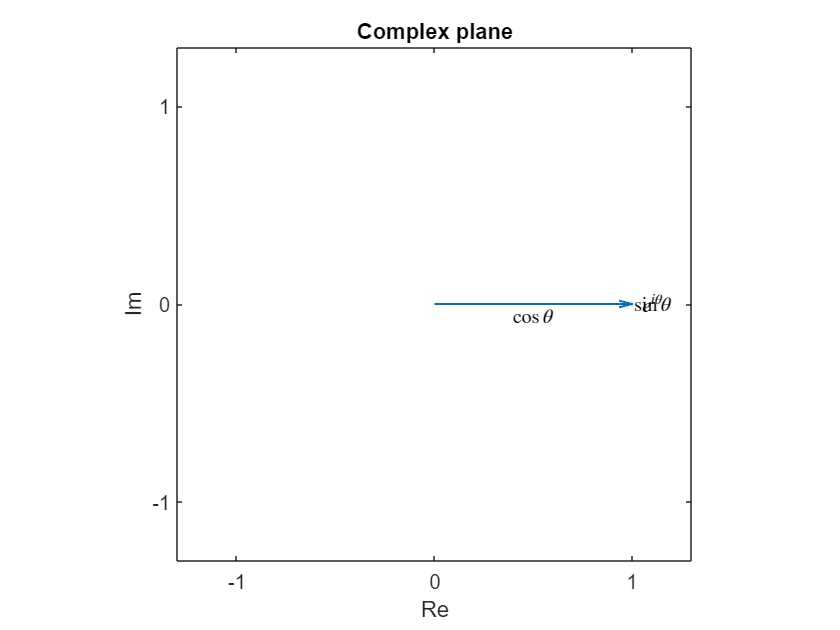

thetad = 0; % In degrees
complexCircle(thetad); % Helper function that generates the plot

By making the input $\theta$ a linear function of time, Euler's formula will trace out a circle with a speed that depends on the angular frequency $\omega$:


$$y(t) = e^{ i \omega t}$$


The angular frequency has units of rad/s. Plotting each component separately with respect to time will produce two plots: the real component will trace out a cosine curve, and the imaginary component will trace out a sine curve.

    **Task**. Set the frequency of $y(t)$ in the slider below and then run the section to create an animated plot of $e^{ i \omega  t}$ in the complex plane along with the time series.

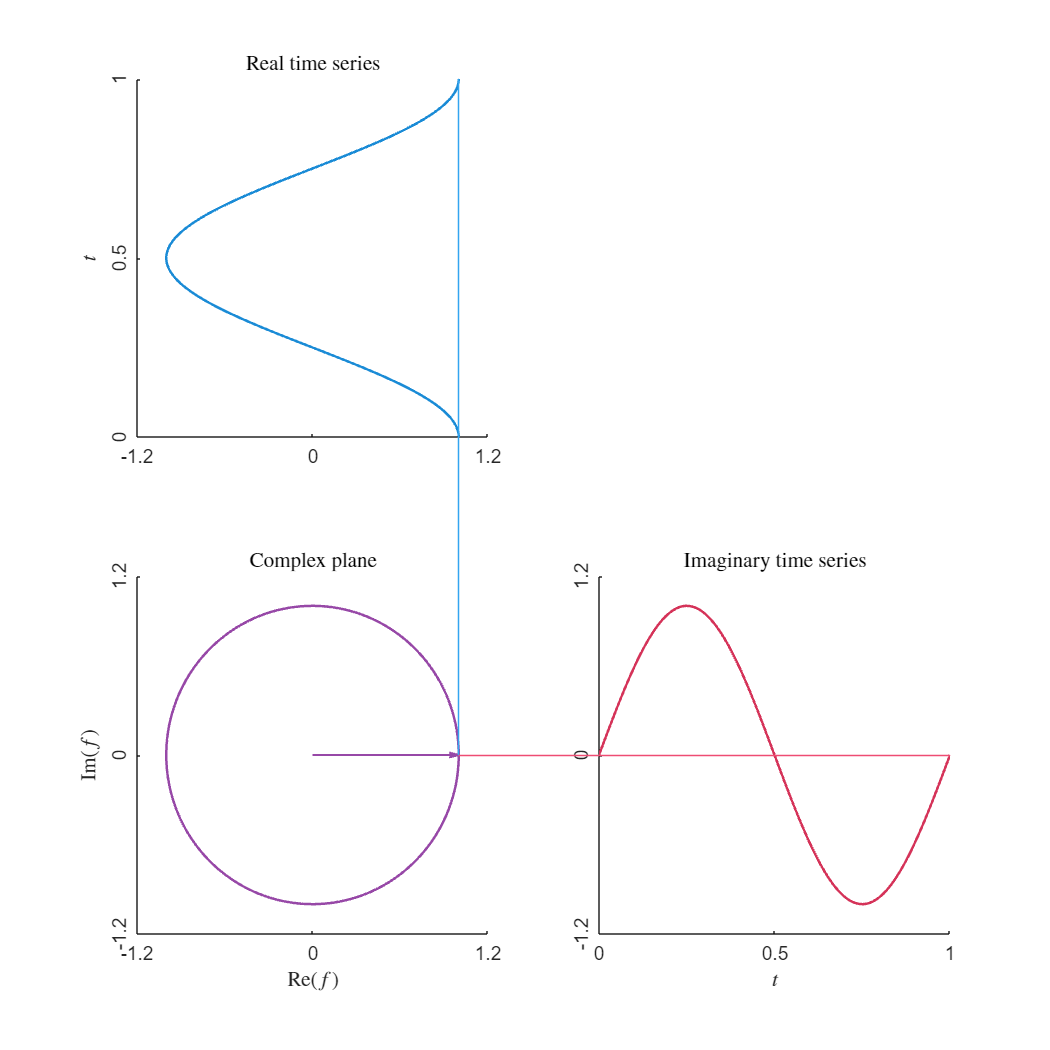

freq = 1; % frequency in Hz
 
omega = freq*2*pi; % angular frequency in rad/s
traceSineCosine(1,omega,0,1.2,true); % Helper function that traces the curve

## Complex Fourier Series

By changing the angular frequency $\omega$ of the function $e^{  i \omega t}$, you can create sine and cosine functions with various frequencies just like those in a standard Fourier series. However, the sines and cosines will be contained in real and complex parts of the function:


$$e^{ i \omega t} = \cos ( \omega t ) + i \sin (\omega t)$$


Combine many different frequencies, and you can accurately capture a periodic signal.

### Definition

The complex Fourier series is defined as:


$$f(t) = \sum_{-\infty}^\infty c_n e^{ \frac{i n \pi}{L} t}$$


In this definition, $f$ is periodic with respect to the domain $[-L,L]$. The fundamental angular frequency $\omega_0$ is related to $L$ through $\omega_0 = \pi/L$. The coefficients of the complex Fourier series can be evaluated using the integral


$$c_n = \frac{1}{2L} \int_{-L}^{L} y(t) e^{ -\frac{i n \pi}{L} t} dt$$


The coefficients may be real or complex. Typically they are complex, but there are special relationships between the coefficients for real functions. But more on that later. 

 **Exercise.** In this exercise, you will compare the complex Fourier series to the standard Fourier series.

**Task 1.** Expand the exponential in the complex Fourier series $f(t)$ defined above using Euler's formula.

**Task 2. **Compare the expanded complex series to the real sine-cosine series:


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


- What parts are the same?

- What parts are different?

### Complex Fourier Series Modes

Complex Fourier series modes are more challenging to understand than real series modes, because they contain both real and imaginary parts. Consider the $n^{th}$ mode of the series:


$$f_n(t) = c_n e^{\frac{i n \pi }{L} t}  = c_n \cos\left( \frac{ n \pi } {L}  t \right) + i c_n \sin \left( \frac{ n \pi } {L}  t \right)$$


Notice that if you set a real mode coefficient, such as $c_n = 1$, you get both a real cosine and imaginary sine curve simultaneously. To understand what this means, it's helpful to visualize a few modes.

    **Activity**. Visualize complex modes in the complex Fourier series app.

**Task 1. **Run the complex Fourier series app.

[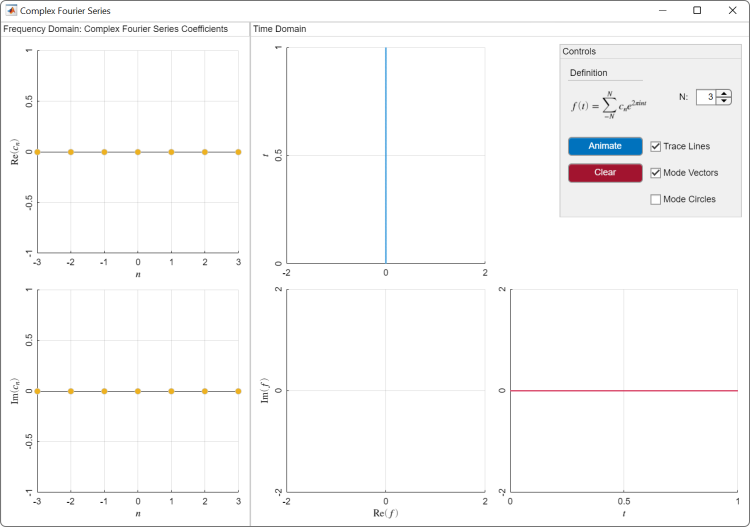](matlab: run ComplexFourierSeries)

[ComplexFourierSeries.mlapp](matlab: run ComplexFourierSeries)

**Task 2. **The frequency domain is shown in the panel on the left side. Adjust the coefficient of the second mode ($n=2$) so that $c_2 = 1$. Leave all other $c_n = 0$.

- You can adjust the modes by clicking and dragging the coefficient stem plot. 

- You only need to adjust the first plot, which contains the real parts of the coefficients.

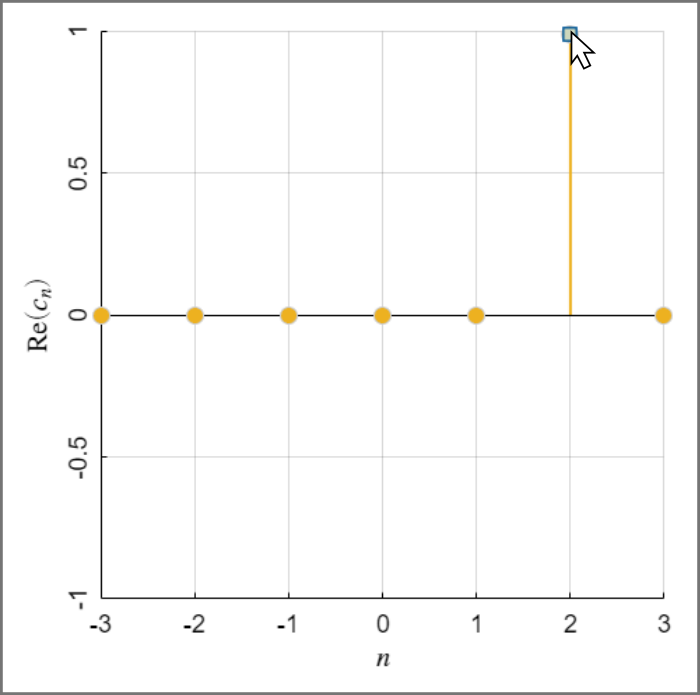

**Task 3. **Review the result displayed in each plot. Review the axes labels and the descriptions below to identify what is shown in each plot.

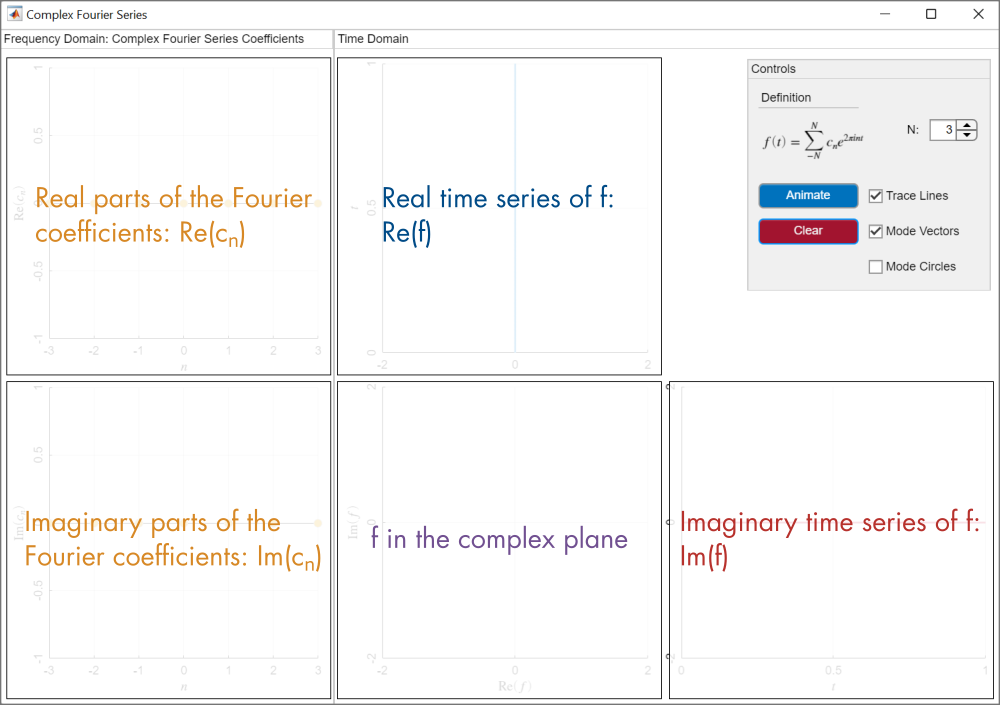

*Descriptions of the plots in the Complex Fourier Series app. Notice that in the real time series, the axes have been flipped so that the real component matches up with the real axis of the complex plane.*

**Task 4. **Press the **Animate **button to animate the mode over time. Notice that the mode contains both real and imaginary components.

**Task 5. **Press the clear button to reset the coefficients.

**Task 6.** Adjust the coefficient of the first mode so that $c_1 = i$ (all other $c_n = 0$) and animate the plot.

- Use the second plot ($\text{Im}(c_n)$) to adjust the imaginary part of the mode coefficient.

- When you changed $c_1$ from $c_1 = 1$ to $c_1 = i$, the complex plot did not change (it still shows a unit circle). However, the time series have changed. How did the real time series change?

**Task 7.** Clear the app. Then, create a mode with a complex coefficient: $c_1 = 1+i$. You need to adjust both the real and imaginary components of the coefficient to 1. 

- How does the complex plot change? 

- How do the real and imaginary time series change?

**Task 8. **Repeat tasks 2-7, but use a higher frequency mode: n = 3. Continue to look at only one mode at a time.

- How does the complex plot change compared to the case where $n = 1$?

- How do the time series plots change compared to the case where $n = 1$?

In **Tasks 2-4**, you set $c_1 = 1$ (while all other $c_n = 0$). This means that the Fourier series consisted of only one mode:

$f(t) = 1 e^{2 \pi i  t}  =  \cos\left(2  \pi  t \right) + i \sin \left( 2 \pi  t \right)$.

Notice that the real component of $f$ is a pure 1 Hz cosine wave (observed in the real time series), and the imaginary component is a pure 1 Hz sine wave (observed in the imaginary time series).

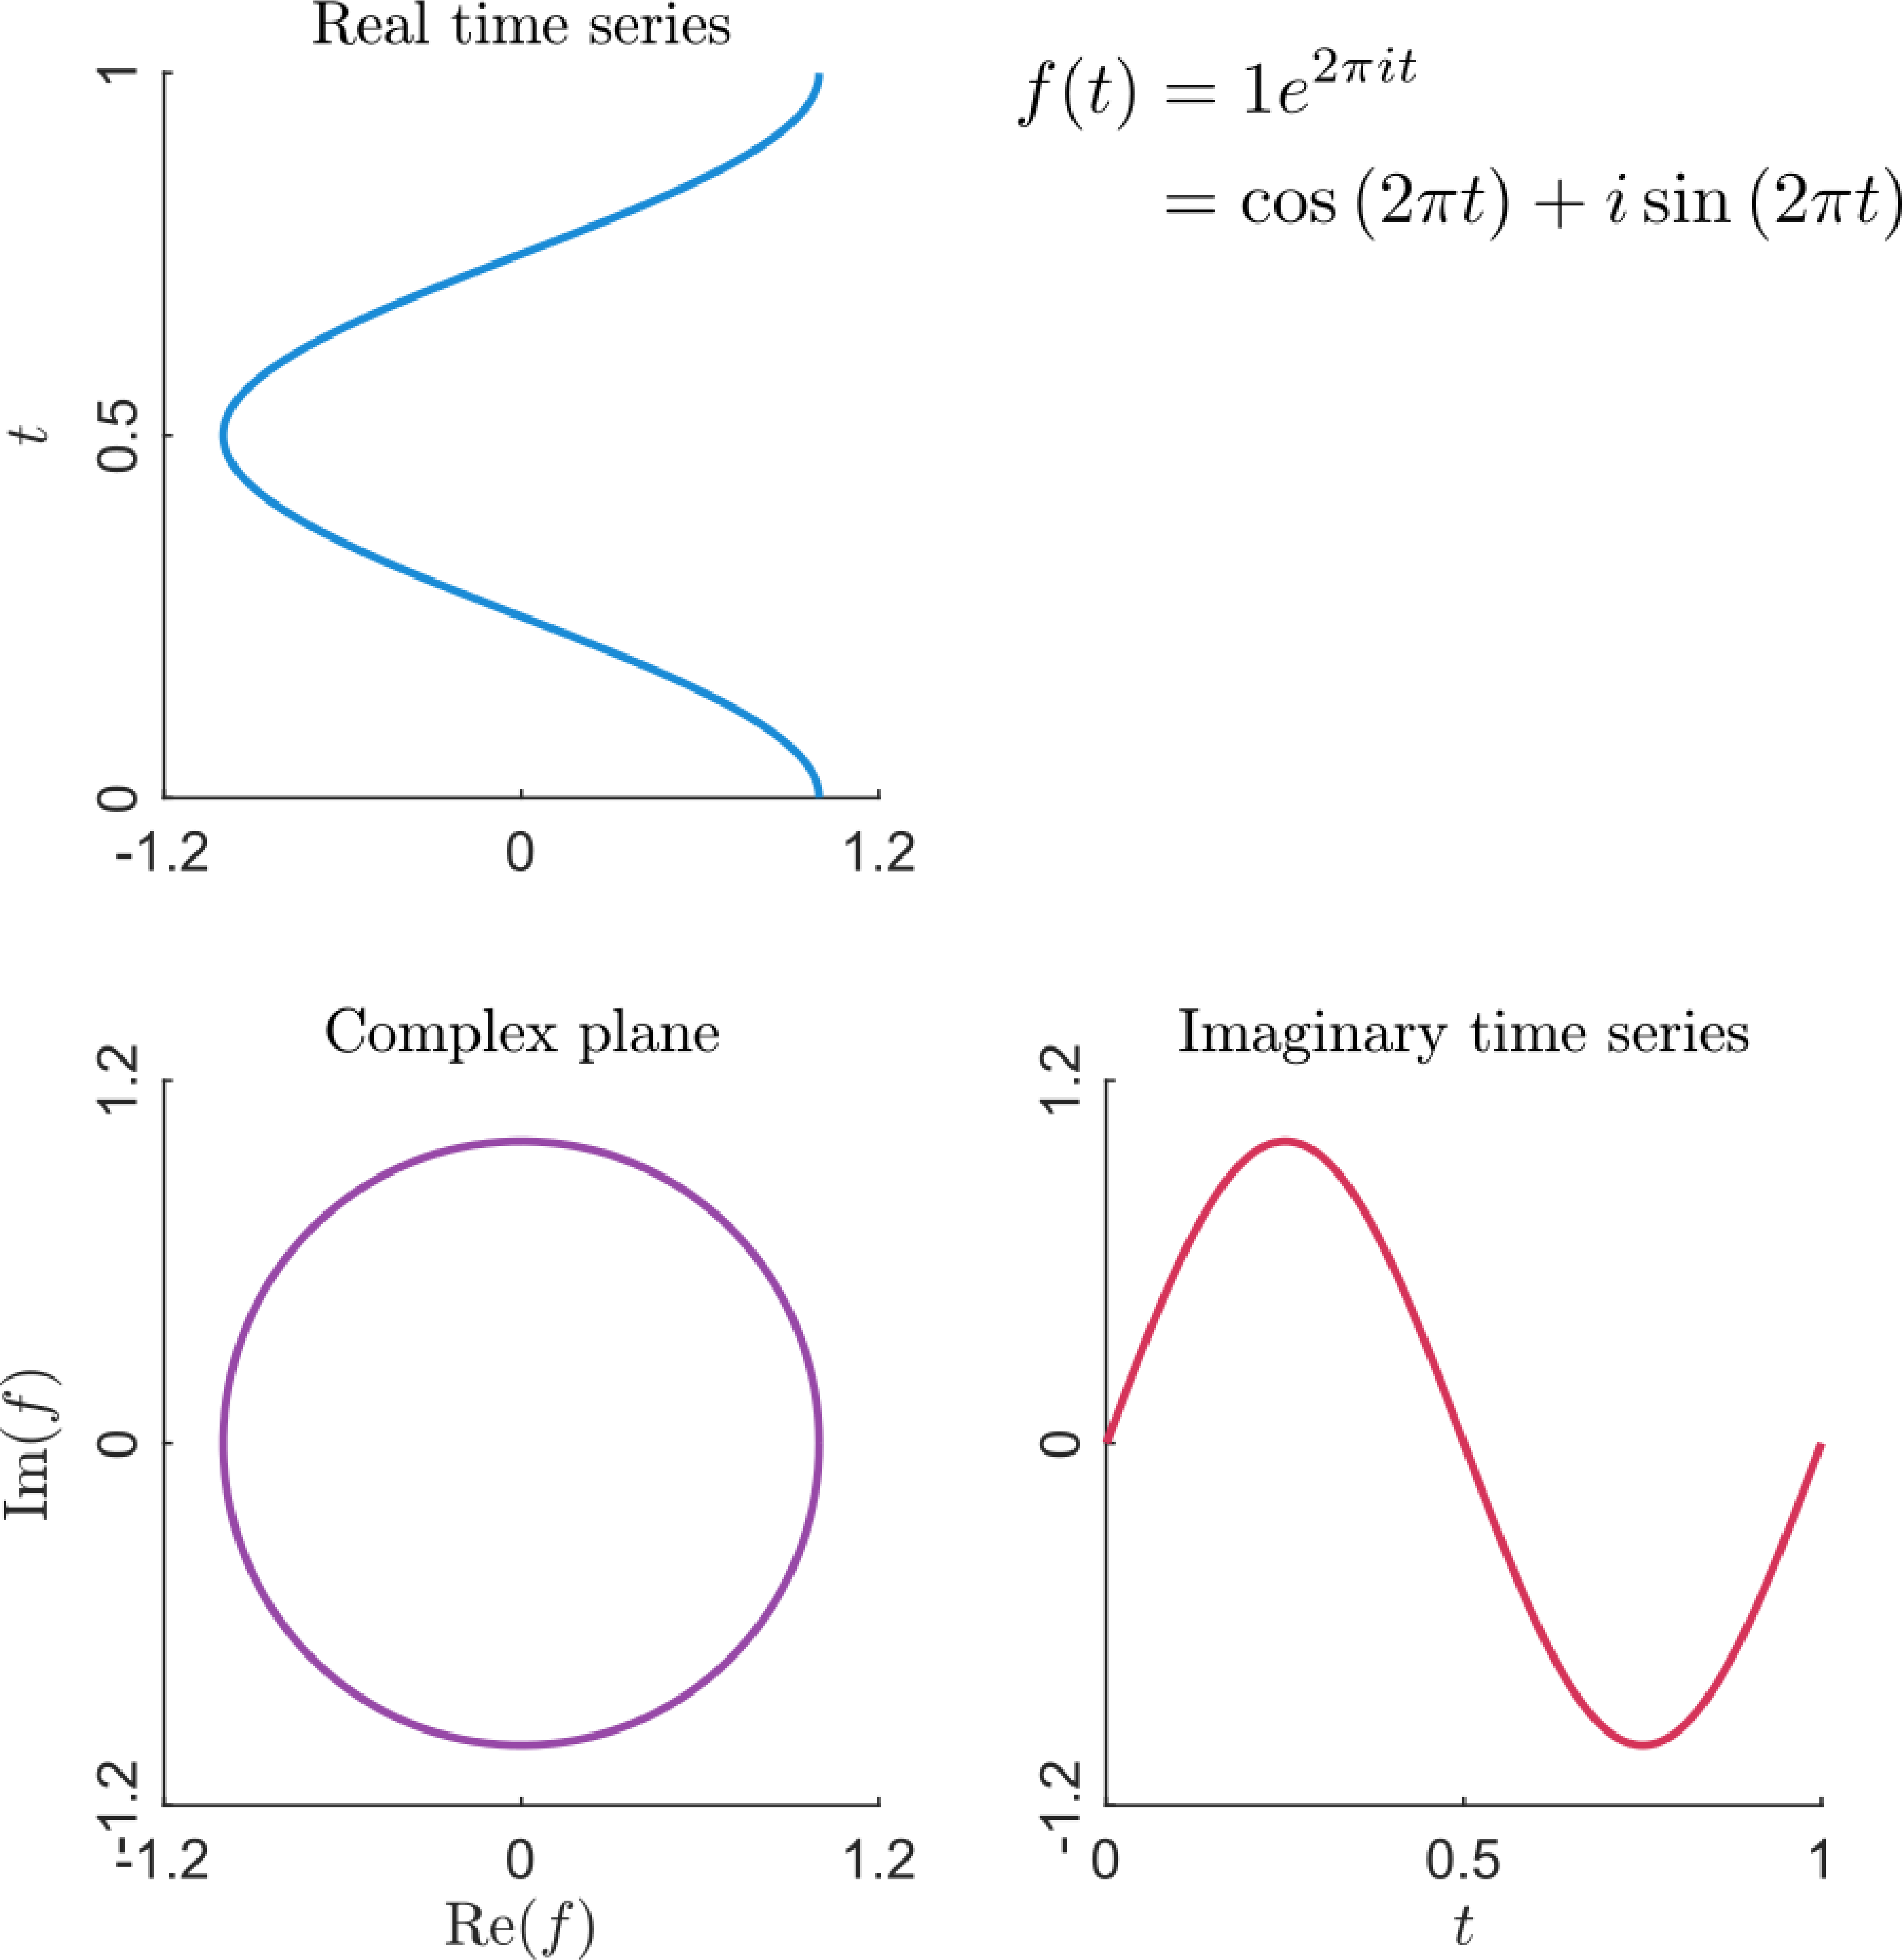

*Time domain plots of *$f$* with a single mode, *$c_1 = 1$.

 **Exercise.** By hand, write out the Fourier series with $c_1 = i$ and all other $c_n = 0$.

- What are the real and imaginary components of the Fourier series, $f$?

- How are these components reflected in the time series plots you observed in the app?

## Representing Real Functions with Complex Series

In the previous activity, you probably noticed that every mode comes with a real and an imaginary component. Indeed, no matter what complex coefficient $c_n$ is selected (except 0), the mode will always contain a combination of real and imaginary parts.

So, how do you create a real-valued function from these modes? For example, what coefficients will create a pure 1 Hz sine wave?


$$y(t) = \sin( 2 \pi t)$$


The answer is to combine positive and negative frequencies "just right" so that the imaginary parts "cancel out."

### Real Modes from Complex

    **Activity**. In this activity, you will create real modes by combining complex modes.

**Task 1. **Run the complex Fourier series app.

[](matlab: run ComplexFourierSeries)

[ComplexFourierSeries.mlapp](matlab: run ComplexFourierSeries)

**Task 2. **Set the Fourier coefficient $c_1 = 0.5$. 

**Task 3. **By adjusting the Fourier coefficient with the same but negative frequency ($c_{-1}$), you can produce a real signal. Adjust the real and/or imaginary part of $c_{-1}$ to produce a real signal.

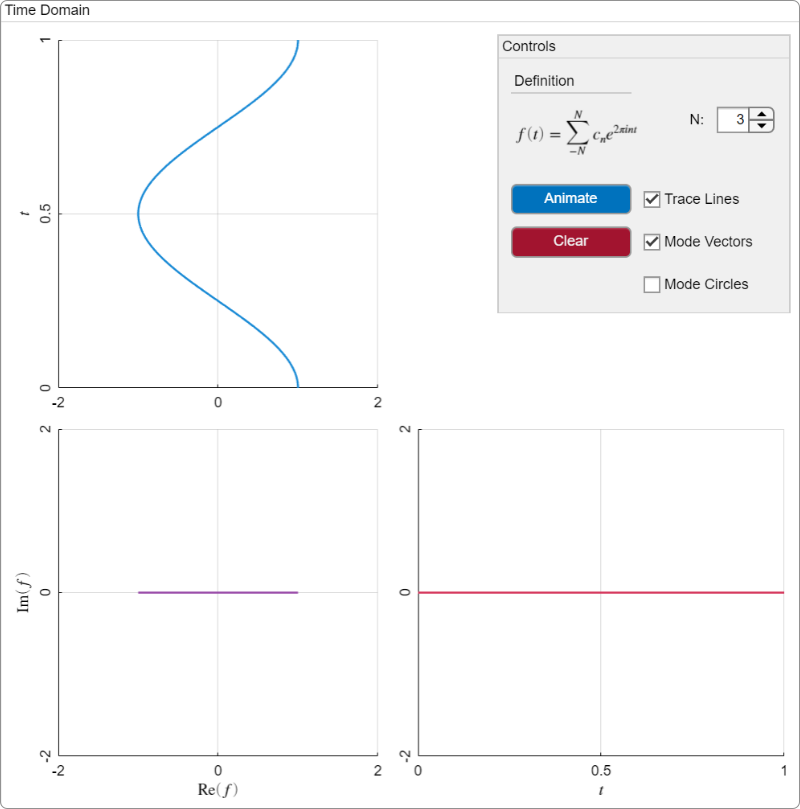

*If correct, you should find that you have created a real cosine curve. The imaginary component should be zero.*

**Task 4. **By hand, write out the Fourier series with the two coefficients that you used in **Tasks 2 **and** 3**. Use the definition given by the app:


$$f(t) = \sum_{-N}^N c_n e^{ 2 \pi i n t}$$


Then, simplify the result by expanding the complex exponentials using Euler's formula. If correct, you should find


$$f(t) = \cos(2 \pi t)$$


**Task 5. **Animate the plot. Notice that both complex modes exist but are combined "just so" to "cancel" the imaginary part.

- Visualize the circular path of each complex mode by selecting the "Mode Circles" checkbox and rerunning the animation.

- Notice that the two complex circles have the same frequency and magnitude but are traversed in opposite directions. This is the result of using a negative frequency component.

**Task 6. **In **Tasks 2-4**, you found the coefficients that would produce a real 1 Hz cosine wave from the complex Fourier transform. Consider the expansion that you did in **Task 4 **with only $c_1$ and $c_{-1}$:


$$f(t) = c_{-1} e^{ - 2 \pi i t} + c_{1} e^{ 2 \pi i t}$$


Can you identify complex coefficients $c_1$ and $c_{-1}$ that will produce a real 1 Hz sine wave? Record your answer below.

**Hint: **expand the complex exponentials using Euler's formula.

  **Pro-tip.** To write a complex number, you can use standard mathematical notation. For example, $w = 3+2i$ can be written in MATLAB as 

% Replace NaN with your answers
cm1 = NaN; % c_{-1}
c1 = NaN; % c_1

**Task 7. **Check your result by setting the coefficients inside the app to the values you identified in** Task 6**. Then, animate the plot. 

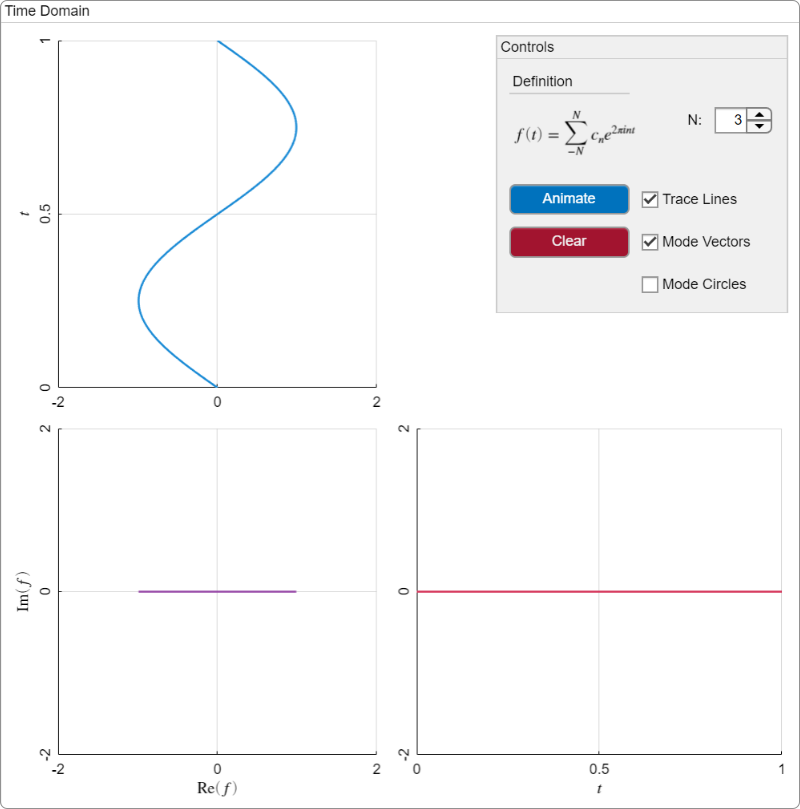

*Correct result*

#### **Relationship between Real and Complex Series**

In general, to produce a real mode, the negative frequency coefficient $c_{-n}$ must be the complex conjugate of the corresponding positive frequency mode: $c_{-n} = {c_n}^*$. Recall that the complex conjugate of $a + bi$ is $a - bi$. You can show that this is exactly what is needed to "cancel out" the imaginary component of the series. This fact leads to the relationship between real and complex Fourier series. Consider the real sine-cosine Fourier series:


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


The corresponding complex Fourier series is

$f(t) = \sum_{-\infty}^\infty c_n e^{ \frac{i n \pi}{L} t}$    with    $c_n = \frac{1}{2} \left\{
 \begin{array}{rl} 
a_0; & n = 0 \\ 
a_n - i b_n; & n > 0 \\ 
a_{-n} + i b_{-n}; & n < 0 \\ 
 \end{array}
 \right.$

 **Exercise.** Write the complex Fourier series in terms of $a_n$ and $b_n$ shown above and apply Euler's formula. Verify that the result is equivalent to the real Fourier series.

### Mode Combinations

In the last activity, you combined complex modes to create real sines and cosines. With those real building blocks, you can combine many frequencies to reproduce a periodic function, just like you would with real Fourier series.

    **Activity**. In this activity, you will combine several complex modes to create a real function.

**Task 1. **Run the complex Fourier series app.

[](matlab: run ComplexFourierSeries)

[ComplexFourierSeries.mlapp](matlab: run ComplexFourierSeries)

**Task 2. **Set the Fourier coefficients to generate the real function:


$$f(t) = \cos( 2 \pi t ) + \cos(6 \pi t )$$


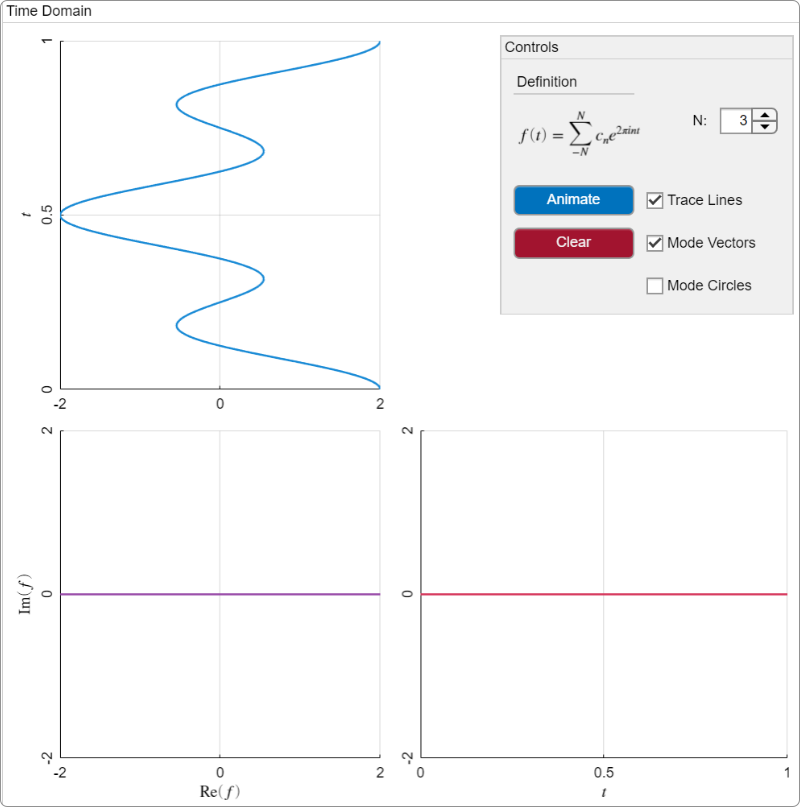

*If correct, your function should appear as a sum of a 1 Hz and 3 Hz sine wave*

**Hint**: create the cosine curves using the positive frequencies first. Then, use the negative frequencies to "cancel out" the imaginary components.

**Task 3. **Animate the plot with (and without) the mode circles drawn. Notice that the high frequency modes spin faster than the low frequency modes, generating the higher frequency oscillations in the time domain plot.

**Task 4. **Repeat **Tasks 2** and **3 **for the real-valued function


$$f(t) = 0.5 + \sin(2 \pi t) + \cos( 2 \pi t) - \sin( 4 \pi t)$$


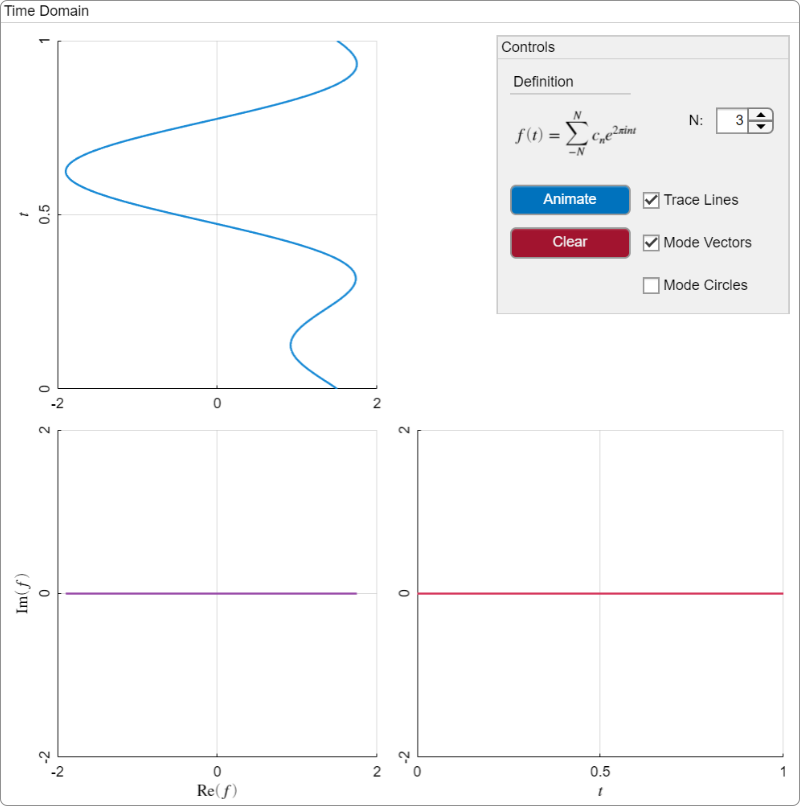

*Correct result*

 **Exercise. **Use the integration formula


$$c_n = \frac{1}{2L} \int_{-L}^{L} y(t) e^{ -\frac{i n \pi}{L} t} dt$$


with $L = 0.5$ (to match the definition in the app) to derive the complex series coefficients for the function 


$$f(t) = \cos( 2 \pi t ) + \cos(6 \pi t )$$


Do they match the result that you found in the activity?

**Hint**: start by rewriting the sines and cosines in terms of complex exponentials using the formulas:

$\cos \theta = \frac{e^{i \theta} + e^{- i \theta}}{2}$    and    $\sin \theta = \frac{e^{i \theta} - e^{- i \theta}}{2i}$

The complex Fourier series for a discrete signal can be estimated using a discrete approximation for the integral in the coefficient formula.

 **Example. **Run this section to see the complex Fourier series coefficients $c_n$ computed for a guitar note.

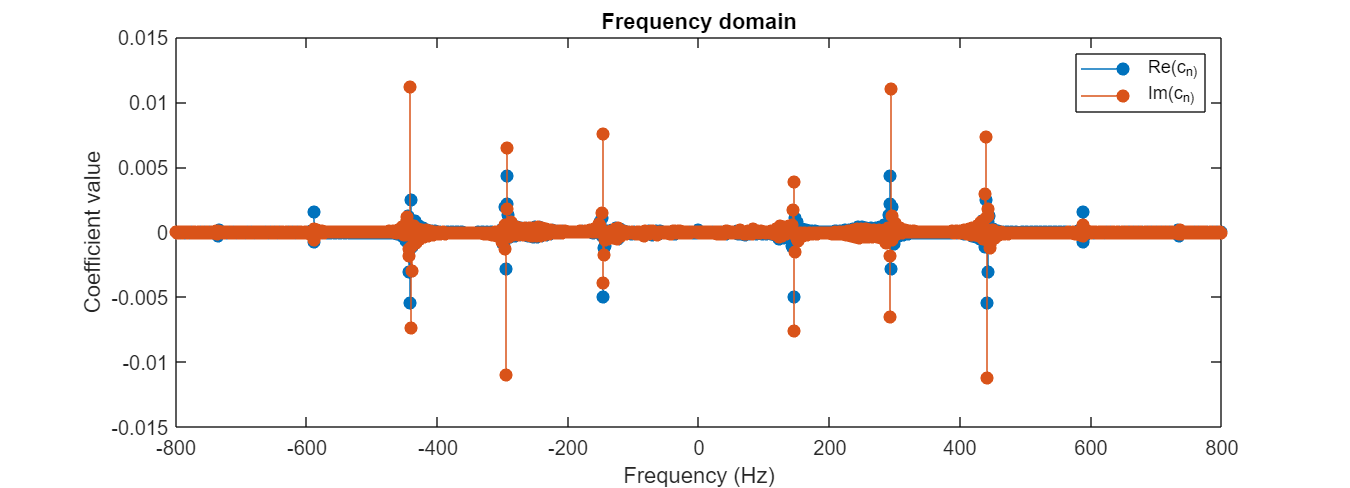

% This code reads and plays the guitar sound 
[yGuitar,FsGuitar] = audioread("Dnote.mp3");
soundsc(yGuitar,FsGuitar)
% This helper function computes the complex Fourier coef
[freq,c] = computeGuitarComplexFourierCoef(yGuitar,FsGuitar);
plotComplexCoef(freq,c); % Generates the plot

**  Reflect.** 

- Which frequency is dominant?

- Observe that the plot is mirrored (with slight differences) across $n = 0$. Why?

- What is the meaning/purpose of the negative frequencies?

### Magnitude and Phase of Complex Series

While it is important to understand the complex coefficients $c_n$ in the standard form ($a+bi$), the plots can be confusing. As with real series, you can plot the phase and magnitude of the complex coefficients to get a clearer picture of the frequency domain. To do so, you need to rewrite the complex coefficients in terms of phase and magnitude. This can be done using the phase-magnitude form of complex numbers:


$$a + bi = A e^{i \phi}$$


where $A$ is the magnitude and $\phi$ is the phase. This is often referred to as *polar form*.

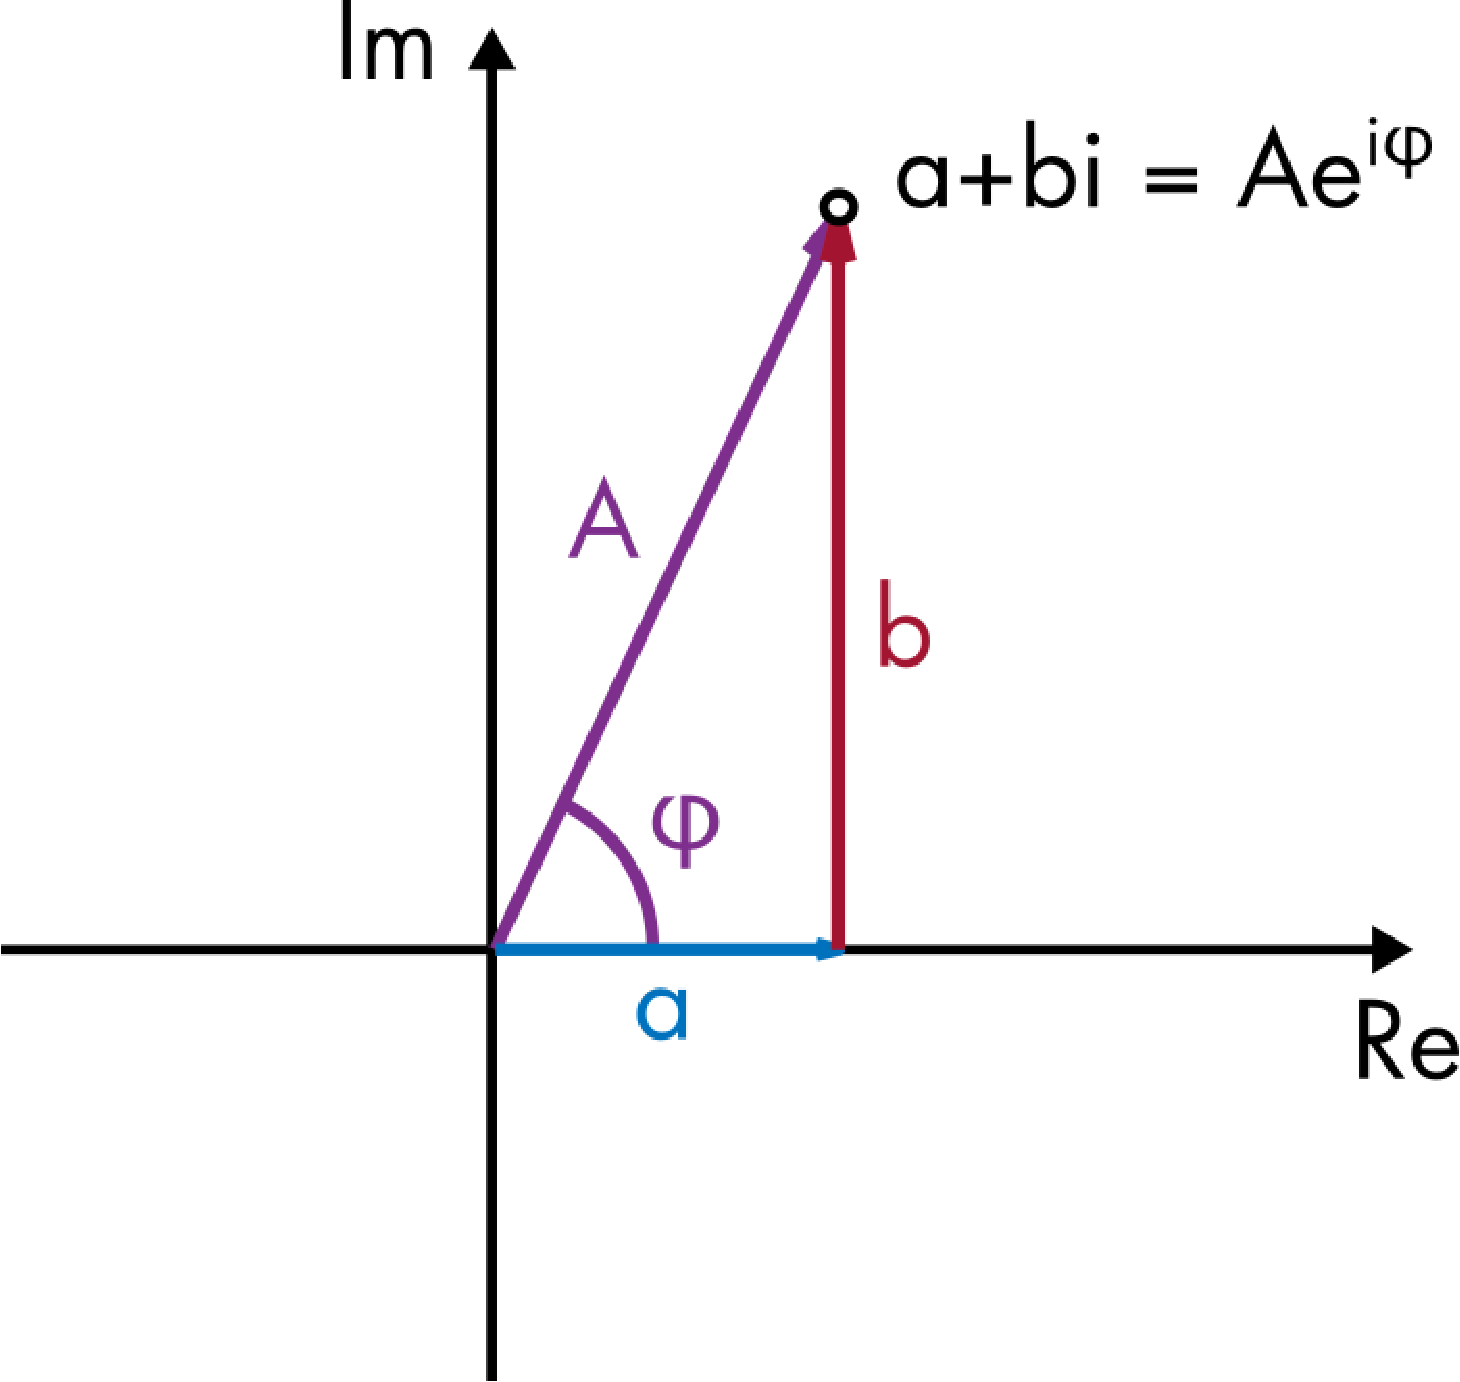

*The standard and polar forms of a complex number visualized in the complex plane*

The magnitude can be computed from the components of $a + bi$ using:


$$A= \sqrt{ a ^2 + b^2}$$


The phase can be computed using `atan2`:


$$\phi = \text{atan2}\left(b,a\right)$$


Look familiar? These are exactly the same formulas used to compute magnitude and phase from the sine and cosine coefficients in a real Fourier series. Using these formulas, you can compute the magnitude and phase shift of any complex Fourier series mode directly from the coefficient $c_n$.

    **Activity**. The code below animates the plot for a single 2 Hz complex mode $f_2(t) = c_2 e^{4 \pi i t}$ with complex coefficient in polar form: $c_2 = A e^{i \phi}$.

- Change the magnitude of the coefficient $A$ and run the animation. How does the mode change?

- Change the phase $\phi$ of $c_2$ and run the animation. How does the mode change?

A = 1; % Complex coefficient magnitude
phi = 0; % Complex coefficient phase
 
cn = A*exp(1i*phi)

cn = 1

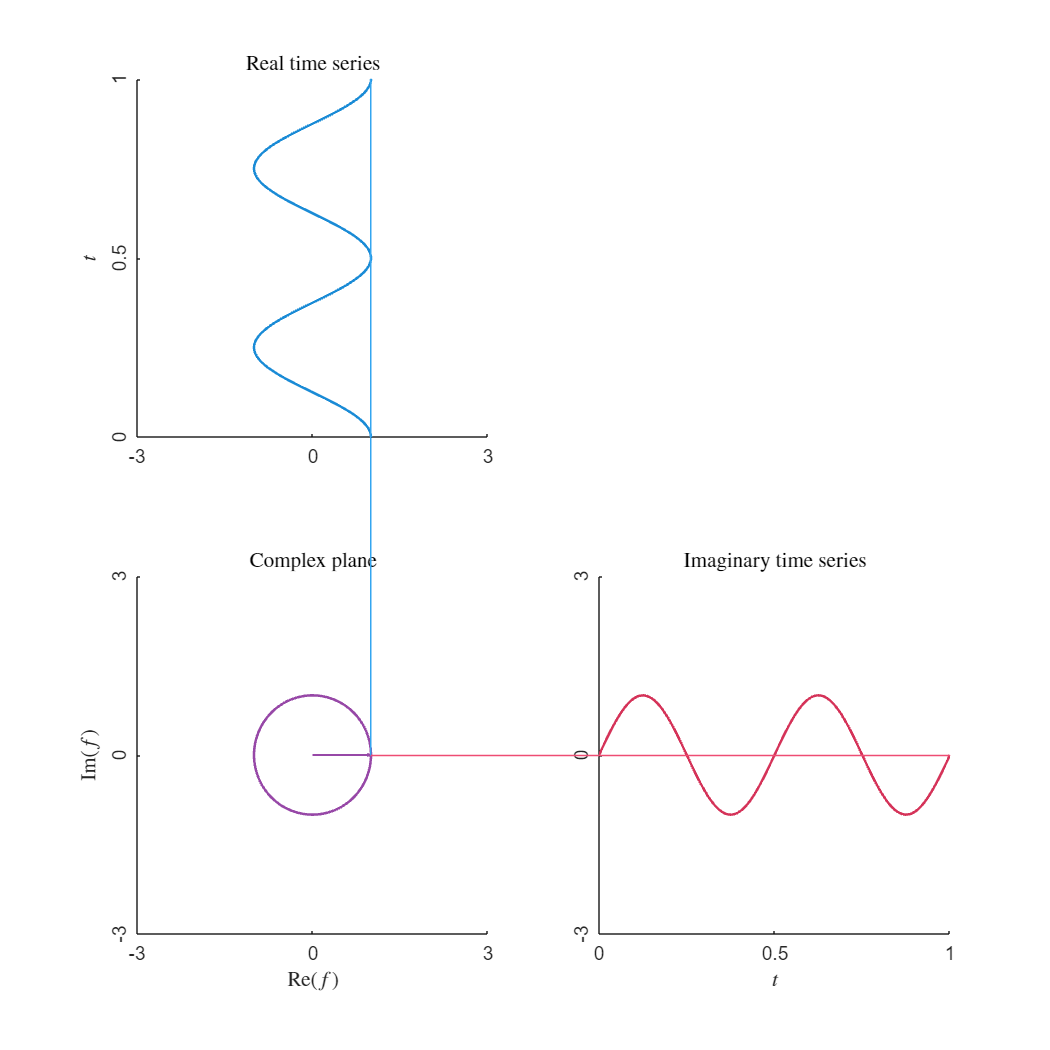

omega = 2*2*pi; % angular frequency of the mode in rad/s
traceSineCosine(A,omega,phi,3,true); % Helper function that generates the plot

After computing the complex Fourier coefficients for a real signal, you can compute the phase and magnitude to create intuitive plots of the Fourier domain.

 **Exercise. **In this section, you will review the magnitude and phase plots of the guitar note.

**Task 1. **Run this section to compute the complex Fourier coefficients. The complex coefficients are stored in the vector `c`.

% This code reads and plays the guitar sound 
[yGuitar,FsGuitar] = audioread("Dnote.mp3");
soundsc(yGuitar,FsGuitar)
% This helper function computes the complex Fourier coef
[freq,c] = computeGuitarComplexFourierCoef(yGuitar,FsGuitar);
 

**Task 2. **Compute the magnitude and phase of the complex coefficients, `c`. You can use the formulas and these functions: [`real`](https://www.mathworks.com/help/matlab/ref/real.html), [`imag`](https://www.mathworks.com/help/matlab/ref/imag.html), [`atan2`](https://www.mathworks.com/help/matlab/ref/atan2.html), and [`sqrt`](https://www.mathworks.com/help/matlab/ref/sqrt.html) or use the [`abs`](https://www.mathworks.com/help/matlab/ref/abs.html) and [`angle`](https://www.mathworks.com/help/matlab/ref/angle.html) functions.

% Compute the magnitude and phase
A = NaN;
phi = NaN;

**Task 3. **Create a stem plot of the magnitude `A` against `freq`. Use the [`stem`](https://www.mathworks.com/help/matlab/ref/stem.html) function. Set the frequency limits to [-800,800] using the [`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html) function.

figure % Creates a new figure
% Create your stem plot here



Notice that the magnitudes of negative frequencies are equal to those of the mirrored positive frequencies. This will always be the case for a real signal, since the negative frequency coefficients are the complex conjugates of the positive coefficients: $c_{-n} = {c_n}^*$.

**Task 4.  **Create a stem plot of the phase `phi` that you computed in **Task 2**. Use the [`stem`](https://www.mathworks.com/help/matlab/ref/stem.html) function. Set the frequency limits to `[-800,800]` using the [`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html) function.

figure % Creates a new figure
% Create your stem plot here



Most of the phases are irrelevant for this signal since they occur at frequencies with negligible magnitude.

**Task 5. **Identify the phase of the two lower frequency peaks (at 146.6 and 294.4 Hz) in radians. Start by marking the correct frequencies with vertical lines using [`xline`](https://www.mathworks.com/help/matlab/ref/xline.html). For example, use `xline(146.6)` to create a vertical line through 146.6 Hz.

After marking the frequencies, you can click on the stem plots to create a tooltip at the right location and read the phase from it. 

% Add your xlines here



**Hint: **If you're finding it difficult to click the right point, pop the figure out to a new figure window using  and enlarge the plot. You can also zoom in on the correct region using the zoom tool.

% Record your answers here
phase_147Hz = NaN; % In radians
phase_294Hz = NaN; % In radians

## **Complex-Valued Functions **

Real-valued functions are only one special case of the more general complex Fourier series. Indeed, the complex Fourier series can represent a wide variety of complex functions. A complex function has a real and imaginary component:


$$f(t) = f_{re}(t) + i f_{im}(t)$$


    **Activity**. The lemniscate is a figure-8 curve that can be described with just four modes of the complex Fourier series. In this activity, you will draw a lemniscate in the app. The lemniscate can be described by the complex-valued function


$$f(t) = \cos (2 \pi t) + \frac{i}{2} \sin (4 \pi t)$$


**Task 1. **Run the Complex Fourier Series app.

[](matlab: run ComplexFourierSeries)

[ComplexFourierSeries.mlapp](matlab: run ComplexFourierSeries)

**Task 2.** The first two modes of the lemniscate describe a real cosine curve with a frequency of 1 Hz. Adjust the Fourier coefficients to create the graph of the real cosine shown below.

**Task 3. **Adjust the coefficients for the $n = 2$ mode to create the imaginary component of the function: $ \frac{i}{2} \sin (4 \pi t)$. If correct, the complex plot should show the lemniscate.

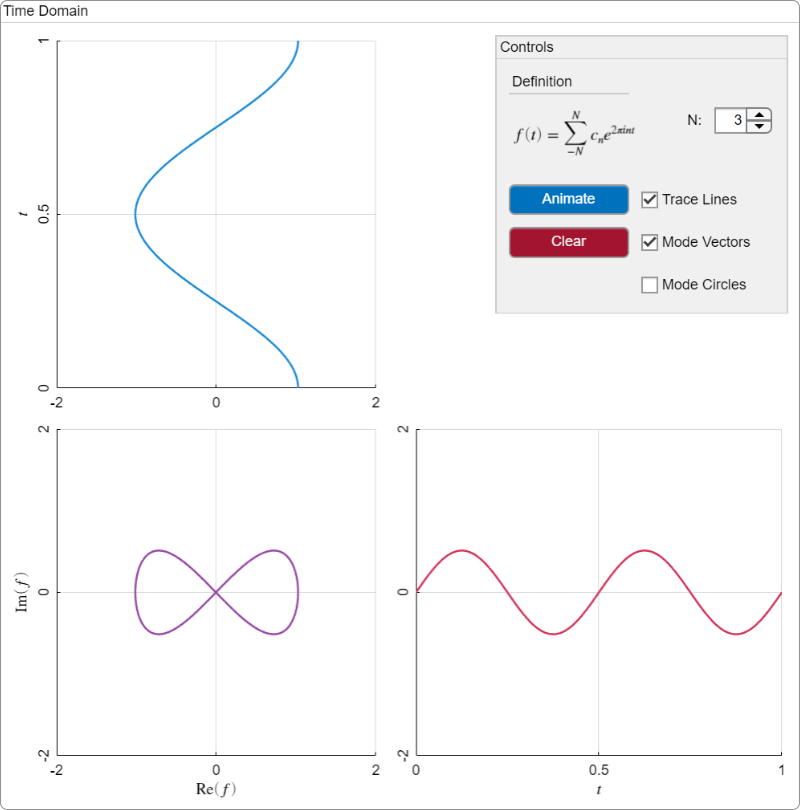

**Task 4**. Animate the plot. 

 **Exercise. **Use the integration formula


$$c_n = \frac{1}{2L} \int_{-L}^{L} y(t) e^{ -\frac{i n \pi}{L} t} dt$$


with $L = 0.5$ (to match the definition in the app) to derive the complex series coefficients for the lemniscate function:


$$f(t) = \cos (2 \pi t) + \frac{i}{2} \sin (4 \pi t)$$


Do they match the result that you found in the activity?

**Hint**: start by rewriting the sines and cosines in terms of complex exponentials using the formulas:

$\cos \theta = \frac{e^{i \theta} + e^{- i \theta}}{2}$    and    $\sin \theta = \frac{e^{i \theta} - e^{- i \theta}}{2i}$

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

**Helper Functions**

function complexCircle(theta)
    % This function traces out a circle in the complex plane
    % With labels for Euler's formula
    
    f = exp(1i*theta * pi/180);
    thetaVec = 0:theta;
    fc = exp(1i*thetaVec*pi/180);
    
    colors = lines(7);
    
    figure
    quiver(0,0,real(f),imag(f),"off","LineWidth",1,"color",colors(4,:))
    hold on
    plot(real(fc),imag(fc),"LineWidth",1,"color",colors(4,:))
    quiver(0,0,real(f),0,"off","LineWidth",1,"color",colors(1,:))
    quiver(real(f),0,0,imag(f),"off","LineWidth",1,"color",colors(7,:))
    text(real(f)/2,0,"$\cos \theta$","Interpreter","latex",...
        "VerticalAlignment","top","HorizontalAlignment","center")
    text(real(f),imag(f)/2,"$\sin \theta$","Interpreter","latex",...
        "VerticalAlignment","middle","HorizontalAlignment","left")
    text(real(f)*1.1,imag(f)*1.1,"$e^{i \theta}$","Interpreter","latex",...
        "VerticalAlignment","middle","HorizontalAlignment","center")
    hold off
    
    axis equal
    axis(1.3*[-1 1 -1 1])
    xlabel("Re")
    ylabel("Im")
    title("Complex plane")
    xticks([-1,0,1])
    yticks([-1,0,1])
end

function [freq,c] = computeGuitarComplexFourierCoef(y,Fs)
    % This function estimates the complex coef. for the 
    % complex Fourier transform using the trapezoid rule

    Nmodes = 1000;
    yc = y(1e4:5e4);
    
    tc = 1/Fs*(0:(length(yc)-1));
    L = tc(end)/2; % The domain is assumed to be 2L
    nvec = -Nmodes:Nmodes;
    freq = nvec/(2*L); % Frequencies

    % Estimate coefficients using trapezoid rule
    c = zeros(1,numel(nvec));
    for k = nvec + Nmodes + 1
        c(k) = 1/(2*L)*trapz(tc,exp(-1i*nvec(k)*pi/L*tc).*yc);
    end
end


function pFig = figPos(ax,p)
    % This function computes the position of points
    % in the figure

    axUnits = ax.Units;
    ax.Units = 'normalized';
    pos = ax.InnerPosition;

    % Shifted so that the origin is at the lower-left corner
    x = p(1)-ax.XLim(1);
    y = p(2)-ax.YLim(1);
    
    % Compute the position of the point in the figure
    xFig = x*(pos(3))/(ax.XLim(2) - ax.XLim(1)) + pos(1);
    yFig = y*(pos(4))/(ax.YLim(2) - ax.YLim(1)) + pos(2);
    
    pFig = [xFig,yFig];
    ax.Units = axUnits;
end

function traceSineCosine(mag,omega,phi,magLim,animateFlag)
    % This function generates the animation of a
    % single Fourier mode
    %
    % Mag: magnitude
    % Omega: angular frequency (rad/s)
    % Phi: phase shift (rad)
    % magLim: axis limits in terms of magnitude
    % animateFlag: whether or not to animate

    freq = omega/(2*pi);

    % This defines the function
    Nt = 150;
    tvec = linspace(0,1,Nt);
    fvec = mag*exp(freq*2*pi*1i*tvec + 1i*phi);
    
    % Appearance settings
    timeColors = [     0    0.4470    0.7410;
        0.7350    0.1000    0.2500;
        0.4940    0.1840    0.5560]+0.1;
    
    imLims = magLim*[-1,1]; % Im limits on complex plane
    reLims = magLim*[-1,1]; % Re limits on complex plane       
    
    lwSeries = 1.25;
    lw = 0.75;

    % Set up the axes
    figure("position",[1,1,700,700])
    ax1 = subplot(2,2,3);
    ax2 = subplot(2,2,1);
    ax3 = subplot(2,2,4);
    
    % Plots
    reLine = plot(ax2,tvec*0,tvec,...
        "linewidth",lwSeries,"color",timeColors(1,:));
    imLine = plot(ax3,tvec,tvec*0,...
        "linewidth",lwSeries,"color",timeColors(2,:));     
    hold(ax1,"on")
    cmplxLine = plot(ax1,tvec*0,tvec*0,...
        "linewidth",lwSeries,"color",timeColors(3,:));
    arrow = quiver(ax1,0,0,0,0,"off","LineWidth",1,"color",timeColors(3,:));
    hold(ax1,"off")

    % Change graph appearance: complex plane
    set(ax1,"XLimMode","manual","YLimMode","manual")
    box(ax1,"off")
    xlim(ax1,reLims)
    ylim(ax1,imLims)
    xticks(ax1,[reLims(1), mean(reLims),reLims(2)])
    yticks(ax1,[imLims(1), mean(imLims),imLims(2)])
    xlabel(ax1,"Re$(f)$","interpreter","latex")
    ylabel(ax1,"Im$(f)$","interpreter","latex")
    title(ax1,"Complex plane","Interpreter","latex")
    ytickangle(ax1,90)
    
    % Graph appearance: real 
    box(ax2,"off")
    set(ax2,"XLimMode","manual","YLimMode","manual")
    xlim(ax2,reLims)
    ylim(ax2,[tvec(1),tvec(end)])
    xticks(ax2,[reLims(1), mean(reLims),reLims(2)])
    yticks(ax2,[tvec(1), mean(tvec),tvec(end)])
    ylabel(ax2,"$t$","interpreter","latex")
    title(ax2,"Real time series","Interpreter","latex")
    ytickangle(ax2,90)
    
    % Graph appearance: imaginary
    box(ax3,"off")
    set(ax3,"XLimMode","manual","YLimMode","manual")
    ylim(ax3,imLims)
    xlim(ax3,[tvec(1),tvec(end)])
    yticks(ax3,[imLims(1), mean(imLims),imLims(2)])
    xticks(ax3,[tvec(1), mean(tvec),tvec(end)])
    xlabel(ax3,"$t$","interpreter","latex")
    title(ax3,"Imaginary time series","Interpreter","latex")
    ytickangle(ax3,90);
    
    crossLine1 = annotation("line",[0,0],[0,0],...
        "LineStyle","-","LineWidth",lw,"color",timeColors(1,:)+0.1);
    crossLine2 = annotation("line",[0,0],[0,0],...
        "LineStyle","-","LineWidth",lw,"color",timeColors(2,:)+0.1);
    
    kvec = 1:numel(tvec);
    if(~animateFlag)
        kvec = kvec(end);
        delete(crossLine1);
        delete(crossLine2);
    end

    for k = kvec
        t = tvec(k);
        f = fvec(k);
        
        % This code creates the connecting lines
        pComplex = [real(f),imag(f)];
        pReal = [real(f),t];
        pImag = [t,imag(f)];
        
        pCFig = figPos(ax1,pComplex);
        pRFig = figPos(ax2,pReal);
        pIFig = figPos(ax3,pImag);
        
        % Update the curves
        cmplxLine.XData = real(fvec(1:k));
        cmplxLine.YData = imag(fvec(1:k));
        
        reLine.XData = real(fvec(1:k));
        reLine.YData = tvec(1:k);
        
        imLine.XData = tvec(1:k);
        imLine.YData = imag(fvec(1:k));
        
        arrow.UData = real(fvec(k));
        arrow.VData = imag(fvec(k));
        
        % Create annotation between the axes
        p1 = [real(f),imag(f)];
        p2 = [real(f),t];
        p3 = [t,imag(f)];
        
        p1Fig = figPos(ax1,p1);
        p2Fig = figPos(ax2,p2);
        p3Fig = figPos(ax3,p3);
        
        if(animateFlag)
            crossLine1.X = [p1Fig(1),p2Fig(1)];
            crossLine1.Y = [p1Fig(2),p2Fig(2)];
            
            crossLine2.X = [p1Fig(1),p3Fig(1)];
            crossLine2.Y = [p1Fig(2),p3Fig(2)];
        end

    
        drawnow
    end
end

function plotComplexCoef(freq, c)
    % Creates a plot of the real and imaginary
    % parts of the complex coefficients
    figure("position",[1,1,900,325])
    stem(freq,real(c),"Filled")
    hold on
    stem(freq,imag(c),"Filled")
    hold off
    xlabel("Frequency (Hz)")
    ylabel("Coefficient value")
    legend("Re(c_n)","Im(c_n)")
    title("Frequency domain")
    xlim([-800,800])
end